vx = varX300DD62{:,"vXFromMotor1"}

vx =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



vtheta = varTheta1DD62{:, "vThetaFromMotor"}

vtheta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


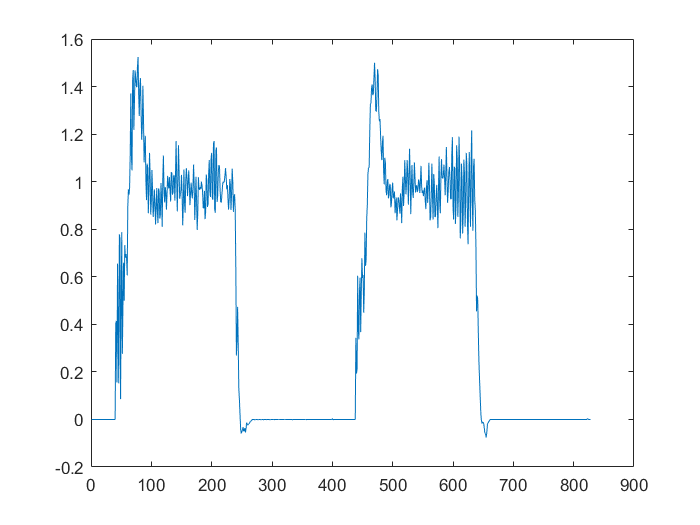

figure()
plot(vtheta(255:length(vx)))

%PT 2 Glied Parameter x/y

K = 1;
A1 = 400-300;
A2 = 300-275;
%T0 = 0.82;
T0=1.5;
D = 1/sqrt(1+3.141^2/log(A1/A2)^2)

D = 0.4038

T = T0 * sqrt(1-D^2)/(2*3.141)

T = 0.2184


s = tf('s');
Gxy = 1/(T^2*s^2+2*D*T*s+1)

G =
 
              1
  --------------------------
  0.04772 s^2 + 0.1764 s + 1
 
Continuous-time transfer function.



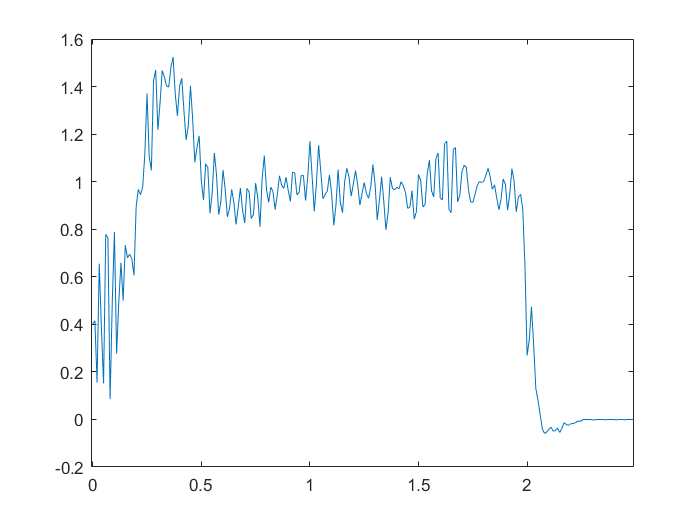

figure()
plot([0:250]*0.01,vtheta(295:295+250))
hold on;

%step(300*G)


%PT2 Glied theta

K = 1;
A1 = 1.4-1;
A2 = 1-0.89;
%T0 = 0.82;
T0=2*(0.69-0.33);
Dtheta = 1/sqrt(1+3.141^2/log(A1/A2)^2)

Dtheta = 0.3802

Ttheta = T0 * sqrt(1-D^2)/(2*3.141)

Ttheta = 0.1060


s = tf('s');
G = 1/(Ttheta^2*s^2+2*Dtheta*Ttheta*s+1)

G =
 
              1
  --------------------------
  0.01124 s^2 + 0.0806 s + 1
 
Continuous-time transfer function.



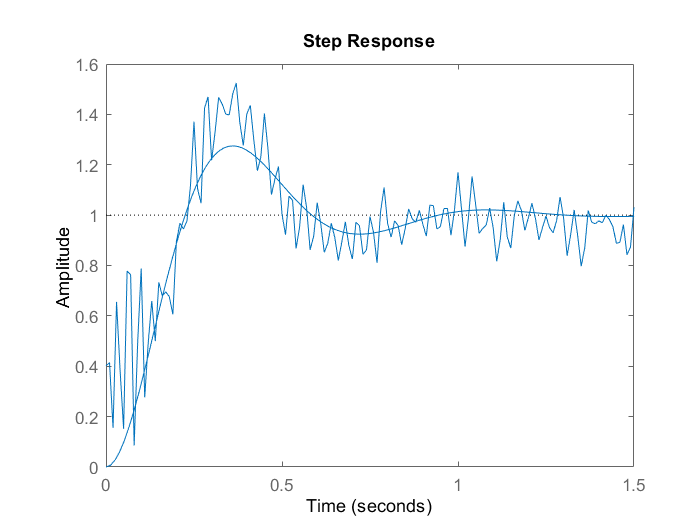


figure()
plot([0:250]*0.01,vtheta(295:295+250))
hold on;
step(G)